# V768 - Measuring Vision with Psychophysics

## Lab 10 - Continuous Psychophysics

In this lab, ...

### Learning Outcomes

(i.e., what you will be able to do at the end of this lab)

- Describe a target-tracking experiment from the perspective of a subject.

- Compare and contrast target-tracking experiments and the 2AFC experiments using the matched experiments in this lab as an example.

### Questions

- Include and write a caption for the figure in ...

- Do you think these experiments are measuring the same thing?  Why or why not?

## Part A. Continuous Psychophysics -- Target Tracking

### Step 1. Data collection

To collect data, open the PsychoPy ".psyexp" file in the folder titled tracking, and run that experiment. The instructions will appear on the screen before the trials begin. A single run of the experiment includes 16 trials.

### Step 2. Load your data

#### Find files for specific participant ID

Before running this section of code, enter the participant ID you used below.

participant_id = "demo";

% check current working directory
data_dir = fullfile("tracking", "data");
if ~exist(data_dir, 'dir')
   error("PsychoPy data folder not found. Try changing your " + ...
       "current MATLAB folder to the folder containing this file.")
end

search_pattern = "demo*.csv";

% find csv files
file_info = dir(fullfile(data_dir, search_pattern));

% change variable classes to make them nicer to work with
file_info = struct2table(file_info);
file_info.name = string(file_info.name);
file_info.folder = string(file_info.folder);

% find files for given participant
file_mask = startsWith(file_info.name, participant_id);
file_info = file_info(file_mask,:);  % keep only those rows

% make sure files were found
n_files = height(file_info);
if n_files==0
    error("No files found.")
else
    disp("data files found:"); disp(file_info.name)
end

data files found:
    "demo_tracking_2022-07-10_11h09.59.071.csv"
    "demo_tracking_2022-07-10_11h11.18.016.csv"
    "demo_tracking_2022-07-10_11h22.29.128.csv"
    "demo_tracking_2022-07-10_11h23.56.450.csv"
    "demo_tracking_2022-07-10_11h25.21.558.csv"



**Confirm that all of your data files are listed above.** There should be one file. (There are more for the demo data).

#### Load and merge data tables

% build full paths
file_info.path = arrayfun(@(d,f) fullfile(d,f), ...
    file_info.folder, file_info.name);

% load data and stack it into one table
warning off;
expt_data = table;
for ff = 1:n_files
    this_data = readtable(file_info.path(ff));
    expt_data = [expt_data; this_data];
end
warning on; clear this_data

% display data table size
n_trials = size(expt_data,1);
fprintf("number of trials = %i\n", n_trials)

number of trials = 20


### Step 3. Visualize your data

We'd like to have a plot that looks a bit like this one (Figure 2 from Bonnen et al 2015).

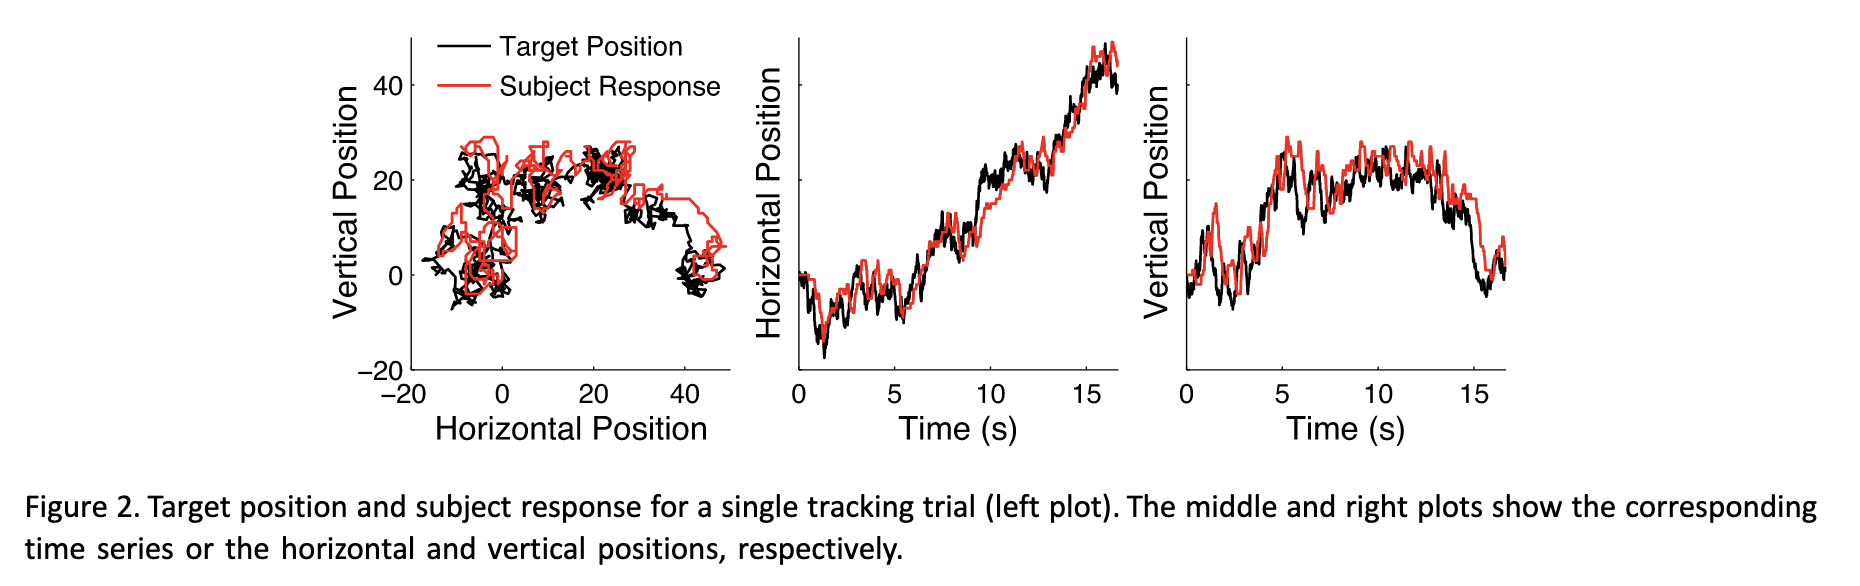

For this experiment, the stimulus was TODO. Both the TODO varied.

For each trial, PsychoPy saved TODO. The responses were stored as TODO.

% extract the target and response positions
target_x = cellfun(@str2num,expt_data.blob_x,'UniformOutput',false);
target_y = cellfun(@str2num,expt_data.blob_y,'UniformOutput',false);
response_x = cellfun(@str2num,expt_data.response_mouse_x,'UniformOutput',false);
response_y = cellfun(@str2num,expt_data.response_mouse_y,'UniformOutput',false);
time = cellfun(@str2num,expt_data.response_mouse_time,'UniformOutput',false);
blob_width = expt_data.blobWidth;

#### Plot the target position and response.

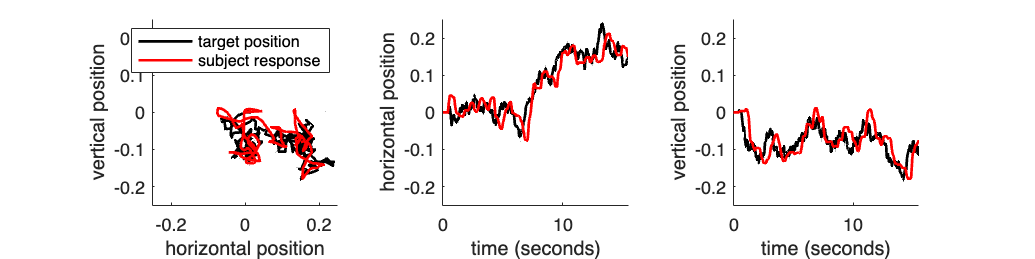

pick_a_trial = 5;
line_width = 1.5;
figure;
subplot(131); hold on;
plot(target_x{pick_a_trial},target_y{pick_a_trial},'k','LineWidth',line_width)
plot(response_x{pick_a_trial},response_y{pick_a_trial},'r','LineWidth',line_width)
xlim([-.25,.25]);
ylim([-.25,.25]);
legend('target position','subject response')
axis square;
xlabel('horizontal position');
ylabel('vertical position');

subplot(132); hold on;
plot(time{pick_a_trial},target_x{pick_a_trial},'k','LineWidth',line_width);
plot(time{pick_a_trial},response_x{pick_a_trial},'r','LineWidth',line_width);
ylim([-.25,.25]);
axis square;
xlabel('time (seconds)');
ylabel('horizontal position');
box off;

subplot(133); hold on;
plot(time{pick_a_trial},target_y{pick_a_trial},'k','LineWidth',line_width);
plot(time{pick_a_trial},response_y{pick_a_trial},'r','LineWidth',line_width);
ylim([-.25,.25]);
axis square;
xlabel('time (seconds)');
ylabel('vertical position');
box off;
set(gcf, 'Position', [0,0, 800 200])

drawnow

#### Step 4. Analyze your data -- Calculating a cross-correllogram 

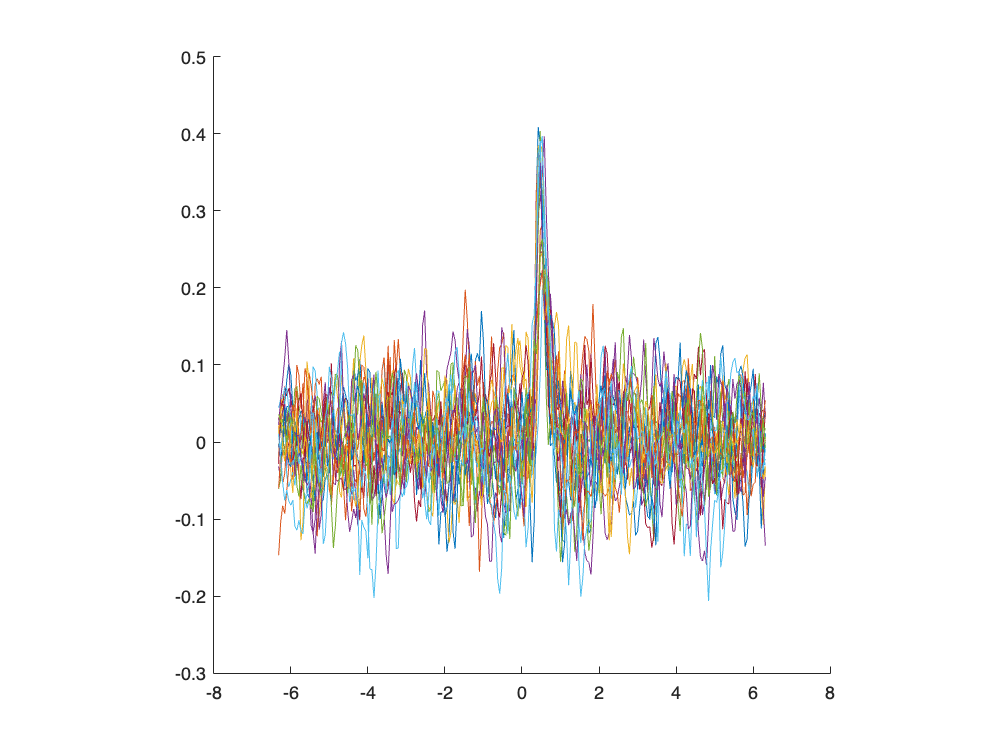

calculate_velocity_ccg = @(x,y) xcorr(diff(x),diff(y),120,'normalized');
ccg_x = cellfun(calculate_velocity_ccg,response_x,target_x,'UniformOutput',false);
ccg_x = cell2mat(ccg_x);
ccg_y = cellfun(calculate_velocity_ccg,response_y,target_y,'UniformOutput',false);
ccg_y = cell2mat(ccg_y);

frameRate = round(1./mean(diff(time{1})));
ccg_x_axis = (-120:120)/frameRate;

figure(); clf;
plot(ccg_x_axis,ccg_x')
box off;
axis square;

drawnow

#### Find the mean CCG per blob width.

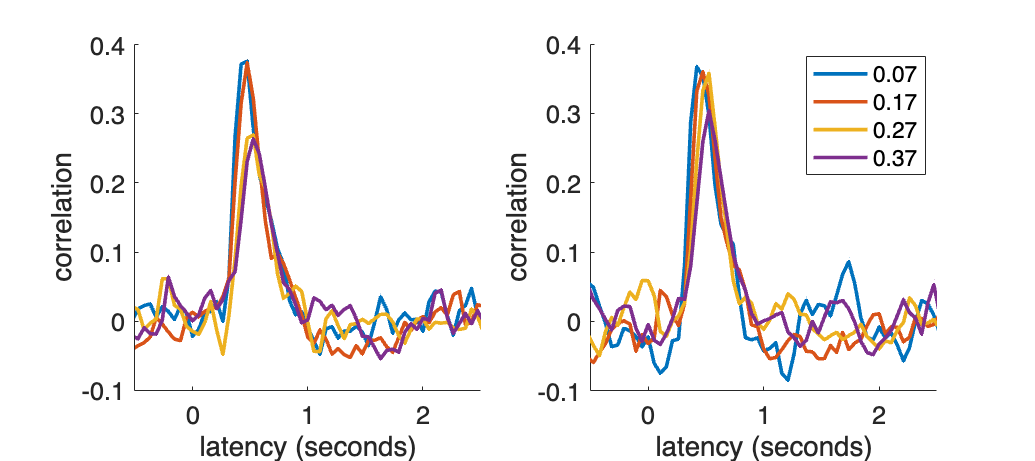

mean_ccg_x = grpstats(ccg_x,blob_width);
mean_ccg_y = grpstats(ccg_y,blob_width);

figure(); clf;
subplot(121);
plot(ccg_x_axis,mean_ccg_x','LineWidth',2)
box off;
axis square;
xlim([-.5,2.5])
xlabel('latency (seconds)');
ylabel('correlation');
set(gca,'FontSize',14)

subplot(122);
plot(ccg_x_axis,mean_ccg_y','LineWidth',2)
box off;
axis square;
set(gcf,'Position',[0,0,900,400]);
xlim([-.5,2.5])
legend(num2str(unique(blob_width)))
xlabel('latency (seconds)');
ylabel('correlation');
set(gca,'FontSize',14)

drawnow;


## Part B. Psychophysics -- 2AFC (Two Alternative Forced Choice)

### Step 1. Data collection

To collect data, open the PsychoPy ".psyexp" file in the folder titled 2afc, and run that experiment. The instructions will appear on the screen before the trials begin. A single run of the experiment includes XX trials.  You should run it **3** times.

### Step 2. Load your data

#### Find files for specific participant ID

Before running this section of code, enter the participant ID you used below.

participant_id = "demo";

% check current working directory
data_dir = fullfile("2afc", "data");
if ~exist(data_dir, 'dir')
   error("PsychoPy data folder not found. Try changing your " + ...
       "current MATLAB folder to the folder containing this file.")
end

search_pattern = "demo*.csv";

% find csv files
file_info = dir(fullfile(data_dir, search_pattern));

% change variable classes to make them nicer to work with
file_info = struct2table(file_info);
file_info.name = string(file_info.name);
file_info.folder = string(file_info.folder);

% find files for given participant
file_mask = startsWith(file_info.name, participant_id);
file_info = file_info(file_mask,:);  % keep only those rows

% make sure files were found
n_files = height(file_info);
if n_files==0
    error("No files found.")
else
    disp("data files found:"); disp(file_info.name)
end

data files found:
    "demo_Bonnen2015_2afc_2022-07-05_01h57.26.528.csv"
    "demo_Bonnen2015_2afc_2022-07-05_11h13.37.777.csv"
    "demo_Bonnen2015_2afc_2022-07-05_11h14.45.111.csv"
    "demo_Bonnen2015_2afc_2022-07-05_11h15.42.746.csv"
    "demo_Bonnen2015_2afc_2022-07-05_11h16.40.299.csv"
    "demo_Bonnen2015_2afc_2022-07-05_11h17.38.154.csv"
    "demo_Bonnen2015_2afc_2022-07-05_11h18.37.343.csv"
    "demo_Bonnen2015_2afc_2022-07-05_11h22.17.093.csv"
    "demo_Bonnen2015_2afc_2022-07-05_11h23.17.519.csv"
    "demo_Bonnen2015_2afc_2022-07-05_11h24.16.192.csv"



**Confirm that all of your data files are listed above.** There should be three files (1 for each run).

#### Load and merge data tables

% build full paths
file_info.path = arrayfun(@(d,f) fullfile(d,f), ...
    file_info.folder, file_info.name);

% load data and stack it into one table
warning off;
twoAFC_data = table;
for ff = 1:n_files
    this_data = readtable(file_info.path(ff));
    this_data(1,:) = [];
    twoAFC_data = [twoAFC_data; this_data];
    
end
warning on; clear this_data

% display data table size
n_trials = size(twoAFC_data,1);
fprintf("number of trials = %i\n", n_trials)

number of trials = 440


For this experiment, the stimulus was TODO. Both the TODO varied.

For each trial, PsychoPy saved TODO. The responses were stored as TODO.

blob_width = twoAFC_data.blobWidth;
offset = twoAFC_data.offset;
response = strcmp(twoAFC_data.key_resp_keys,'right');

## Step 3. Visualize your data

% average across responses per contrast level
twoAFC_analysis_table = table(response,offset, blob_width, ...
    'VariableNames',["response", "offset", "blob_width"]);
twoAFC_expt_results = grpstats(twoAFC_analysis_table, ["offset", "blob_width"]);
twoAFC_expt_results = renamevars(twoAFC_expt_results, ...
    ["GroupCount", "mean_response"], ["n_trials", "prob_correct"]);
twoAFC_expt_results.Properties.RowNames = {};

% stash stimulus levels & counts
blob_width_levels = unique(twoAFC_expt_results.blob_width);
offset_levels = unique(twoAFC_expt_results.offset);

n_width = length(blob_width_levels);
n_offset = length(offset_levels);

% display results
disp(twoAFC_expt_results)

    offset    blob_width    n_trials    prob_correct
    ______    __________    ________    ____________

    -0.16        0.07          10             0     
    -0.16        0.12          10             0     
    -0.16        0.17          10           0.1     
    -0.16        0.22          10             0     
    -0.08        0.07          10             0     
    -0.08        0.12          10             0     
    -0.08        0.17          10             0     
    -0.08        0.22          10             0     
    -0.04        0.07          10             0     
    -0.04        0.12          10             0     
    -0.04        0.17          10             0     
    -0.04        0.22          10             0     
    -0.02        0.07          10             0     
    -0.02        0.12          10             0     
    -0.02      

#### Plot ...

...

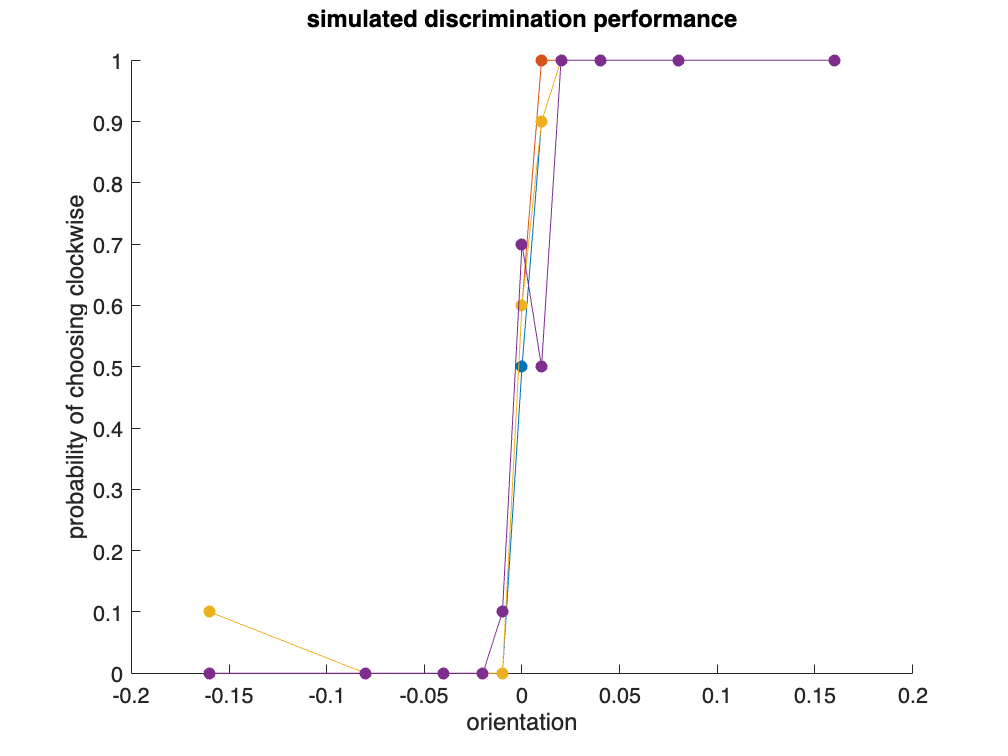

figure; clf; hold on
for i_width = 1:n_width
    idx = twoAFC_expt_results.blob_width == blob_width_levels(i_width);
    plot(twoAFC_expt_results.offset(idx),twoAFC_expt_results.prob_correct(idx),'.-','MarkerSize',20);
end
set(gca,'FontSize',12);
title(["simulated discrimination performance",""])
xlabel("orientation"); ylabel("probability of choosing clockwise");

drawnow

init_params = [0,1,0,0];

for i_width = 1:n_width
    idx = twoAFC_expt_results.blob_width == blob_width_levels(i_width);
    [twoAFC_expt_params(:,i_width), neg_log_likelihood] = fmincon(@(params) ...
        negLogLikelihood(params,...
        twoAFC_expt_results.offset(idx),...
        twoAFC_expt_results.prob_correct(idx).*twoAFC_expt_results.n_trials(idx),...
        twoAFC_expt_results.n_trials(idx)), init_params,...
        [],[],[],[],[-.2,0,0,0],[.2,100,.5,.5]);
end


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum possible. Constraints satisfied.

fmincon stopped because the 

conditions = mat2cell(num2str(blob_width_levels),ones(n_width,1),4);
disp(array2table(twoAFC_expt_params.', 'VariableNames',conditions, ...
    'RowNames',["mu","sigma","gamma","lambda"]))

                 0.07          0.12          0.17          0.22   
              ___________    _________    __________    __________

    mu          0.0012211     0.005836    2.1777e-06    6.6129e-06
    sigma     -0.00049455    0.0019521    9.9972e-06    9.9975e-06
    gamma      0.00046197    0.0059937      0.020841    2.2773e-06
    lambda      0.0021923     0.011236    2.1022e-08    2.9464e-08



**What do you see?** ...